disp("Start simulation of model")

Start simulation of model



%Initialise data and filter
load mpu9250new.mat sensorCalibration

sensorData = array2table(sensorCalibration, 'VariableNames', ["time", "gx", "gy", "gz", "ax", "ay", "az", "mx", "my", "mz"])

sensorData = 101×10 table
    time      gx       gy       gz       ax       ay      az       mx        my       mz  
    _____    _____    _____    _____    _____    ____    ____    ______    ______    _____

        0        0        0        0        0       0       0         0         0        0
     9338     0.53     0.71    -0.07    -0.01    0.01    1.01     -64.1    -26.18    28.34
     9439     0.08     0.04     0.02        0    0.01    1.01    -65.32    -24.61    28.17
     9540    -0.01        0        0        0       0    1.01     -64.1    -26.18    27.66
     9641     0.01     0.06     0.02        0       0    1.01    -64.45    -26.53    27

Fs = 10;
acceleration = [sensorData.ax sensorData.ay sensorData.az]

acceleration =          0         0         0
   -0.0100    0.0100    1.0100
         0    0.0100    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100


gyroscope = [sensorData.gx sensorData.gy sensorData.gz]

gyroscope =          0         0         0
    0.5300    0.7100   -0.0700
    0.0800    0.0400    0.0200
   -0.0100         0         0
    0.0100    0.0600    0.0200
   -0.0200         0   -0.0400
   -0.0400   -0.0300   -0.0100
   -0.0200         0   -0.0600
   -0.0400    0.0100         0
    0.0400    0.1000   -0.0300


magnetometer = [sensorData.mx sensorData.my sensorData.mz]

magnetometer =          0         0         0
  -64.1000  -26.1800   28.3400
  -65.3200  -24.6100   28.1700
  -64.1000  -26.1800   27.6600
  -64.4500  -26.5300   27.6600
  -66.7200  -26.3600   28.1700
  -65.6700  -25.6600   28.1700
  -65.6700  -26.7000   29.8600
  -64.9700  -25.3100   29.5200
  -64.9700  -25.6600   29.1800


decim = 1;
time = (0:decim:size(acceleration,1)-1)/Fs

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


fuse = ahrsfilter("SampleRate", 10, "DecimationFactor", decim);
limit = size(time, 2);

q = fuse(acceleration(2:limit, :), gyroscope(2:limit, :), magnetometer(2:limit, :))

q = 100×1 quaternion array
        0.19848 -   0.029676i +   0.039384j +    0.97886k
         0.1975 -   0.028165i +   0.044068j +    0.97891k
        0.19784 -    0.02645i +   0.043619j +    0.97891k
        0.19731 -   0.027682i +   0.044583j +    0.97894k
        0.19959 -   0.026661i +   0.043439j +    0.97855k
        0.20036 -   0.024342i +   0.041104j +    0.97856k
         0.2037 -   0.023087i +   0.039959j +    0.97795k
        0.20374 -   0.022529i +   0.038092j +    0.97802k
        0.20526 -   0.025604i +   0.040841j +    0.97752k
        0.20706 -   0.027148i +   0.038911j +    0.97718k
        0.20723 -   0.026073i +   0.037917j +    0.97721k
        0.20923 -   0.024717i +   0.038204j +    0.97681k
        0.20966 -   0.024526i +   0.034362j +    0.97686k
        0.20821 -   0.023936i +   0.033526j +    0.97722k
        0.20905 -    0.02828i +   0.034251j +     0.9769k
        0.21029 -   0.032112i +   0.032834j +    0.97656k
        0.21106 -   0.035201i +    0.03275j +

g = [0 0 1.01];
qg = quaternion([0 g]);
g_ = q(:).*qg;
g_ = g_.*q(:).conj

g_ = 100×1 quaternion array
              0 -   0.042888i +   0.089772j +     1.0051k
     2.7756e-17 -   0.038112i +   0.098375j +     1.0045k
    -2.7756e-17 -   0.034869i +   0.096822j +     1.0047k
     2.7756e-17 -   0.036971i +   0.099195j +     1.0044k
              0 -   0.035187i +   0.096614j +     1.0048k
              0 -   0.031482i +   0.091102j +     1.0054k
              0 -   0.029166i +   0.088436j +     1.0057k
              0 -   0.028831i +   0.084528j +      1.006k
              0 -   0.033624i +    0.09126j +     1.0053k
              0 -   0.037313i +   0.088162j +     1.0055k
              0 -   0.035596i +    0.08576j +     1.0057k
              0 -   0.032625i +   0.085828j +     1.0058k
              0 -   0.033844i +   0.078192j +     1.0064k
     2.7756e-17 -    0.03315i +   0.076246j +     1.0066k
    -2.7756e-17 -   0.041343i +   0.079531j +      1.006k
              0 -   0.049399i +   0.078412j +     1.0057k
     2.7756e-17 -   0.055458i +   0.079594j 


[r,x,y,z] = parts(g_);

% calculate position
acceleration(2:limit,:) = acceleration(2:limit,:) 

acceleration =          0         0         0
   -0.0100    0.0100    1.0100
         0    0.0100    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100


acceleration(2:limit,:) = acceleration(2:limit,:) - [x(1:100) y(1:100) z(1:100)] - [0.0315 -0.0541 0.0026]

acceleration =          0         0         0
    0.0014   -0.0257    0.0023
    0.0066   -0.0343    0.0029
    0.0034   -0.0427    0.0027
    0.0055   -0.0451    0.0030
    0.0037   -0.0425    0.0026
   -0.0000   -0.0370    0.0020
   -0.0023   -0.0343    0.0017
   -0.0027   -0.0304    0.0014
    0.0021   -0.0372    0.0021


velocity = zeros(length(acceleration), 3);
for i = 2:length(acceleration) 
        velocity(i,:) = velocity(i-1,:) + (acceleration(i,:)+acceleration(i-1,:))/(2*Fs);
end

position = zeros(length(velocity), 3);
for i = 2:length(velocity) 
        position(i,:) = position(i-1,:) + (velocity(i,:)+velocity(i-1,:))/(2*Fs);
end

disp(mean(acceleration(:,:)))

   1.0e-03 *

    0.3561   -0.5114   -0.0192



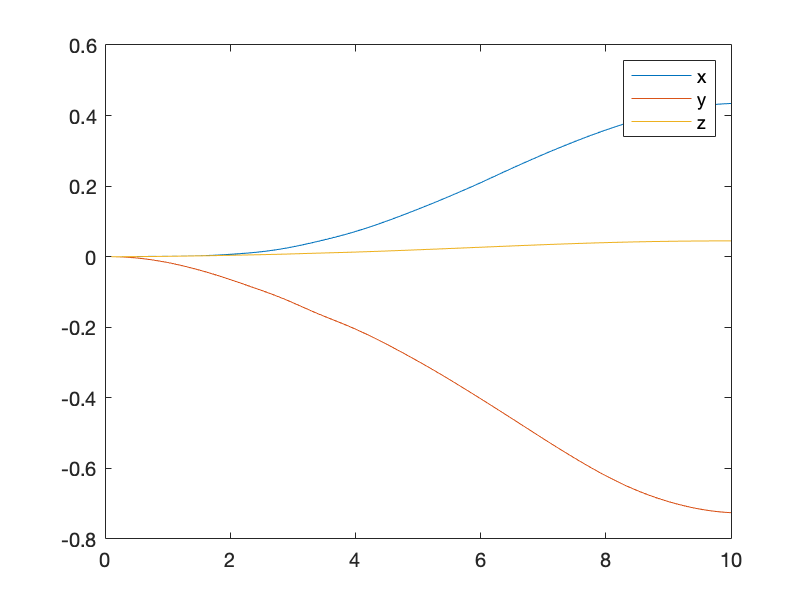


plot((time(2:limit))', position(2:limit,:))
legend("x","y","z")

%initialise pose plot
pp = poseplot

pp =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


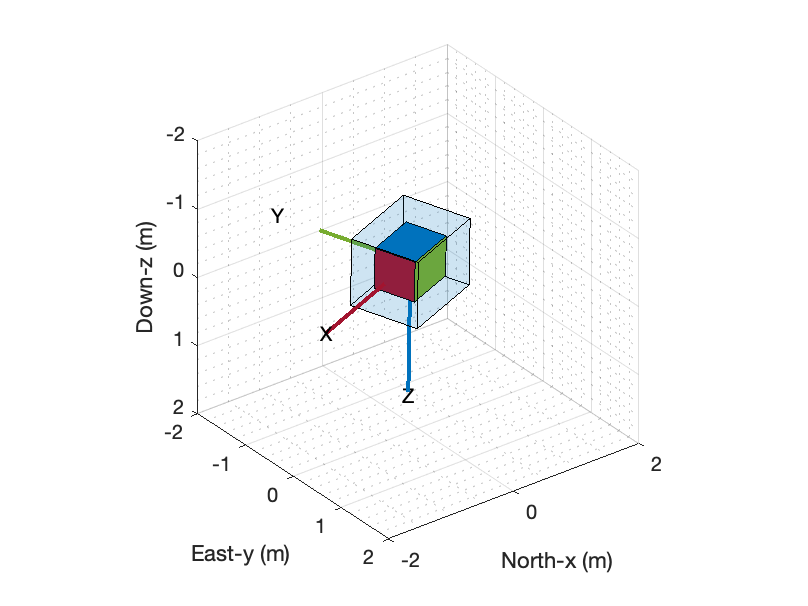

xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");
xlim([-2.00 2.00])
ylim([-2.00 2.00])
zlim([-2.00 2.00])
pos = [0 0 0];

%Create orientation matrix
for i = 2:limit
    q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
    pos = position(i,:);
    set(pp, Orientation = q, Position = pos);
    drawnow
end


%Start reading values and then fuse them
%c = size(time, 2)
%for i = 1:c
 %   q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
  %  plot(time(i), eulerd(q, "ZYX", "frame"), "MarkerSize", 20);
%end
